## Solución numérica del sistema de Lorenz

En este ejemplo emplearemos métodos numéricos (forward Euler) para resolver las ecuaciones diferenciales que describen el sistema de Lorenz:


$$\dot{x}_1=\sigma(x_2-x_1) \\
\dot{x}_2=x_1(\rho-x_3)-x_2 \\ 
\dot{x}_3=x_1x_2-\beta x_2$$


Primero, y lo más importante, se define la dinámica del sistema (el campo vectorial) ya sea en forma de una función anónima o un archivo de función por aparte (ej: dynamics.m).

rho = 28; 
sigma = 10; 
beta = 8/3; 

f = @(x) [ sigma*(x(2)-x(1)); 
           x(1)*(rho-x(3))-x(2); 
           x(1)*x(2)-beta*x(3)  ];

Ya con la dinámica definida se procede a establecer los parámetros de la solución numérica (simulación).

t0 = 0; % tiempo inicial
tf = 50; % tiempo (final) de simulación
dt = 0.01; % período de muestreo
K = (tf - t0) / dt; % número de iteraciones (ya que se utilizará un ciclo for)

x0 = [0.1; 0; 0]; % vector de condiciones iniciales
x = x0; % se inicializa el vector de estado con las condiciones iniciales

Dado que la solución del sistema de EDOs implica la evolución del estado, debemos guardar todos los valores que va tomando el vector de estado. Desde otra perspectiva, la simulación del sistema dinámico requiere que grafiquemos cómo va cambiando el vector de estado iteración por iteración, por lo que es necesario que definamos un array auxiliar para ir guardando cada valor del vector de estado.

X = zeros(numel(x0), K+1); % se deja una casilla para cada iteración más una para x0 
X(:,1) = x; % se almacena de una vez x0

Con todas las definiciones hechas, procedemos a efectuar la "simulación" del sistema dinámico al resolver de forma iterativa, mediante el método de forward Euler, el sistema de EDOs. Recordatorio, cada vez que se genere un nuevo valor del estado este debe almacenarse en el array auxiliar.

for k = 1:K
    x = x + f(x)*dt; % fórmula de forward Euler
    X(:, k+1) = x; % se guardan los valores del estado
end

Finalmente, con las EDOs resueltas procedemos a graficar los resultados de la simulación. Podemos ver primero la evolución de cada variable de estado conforme avanza el tiempo:

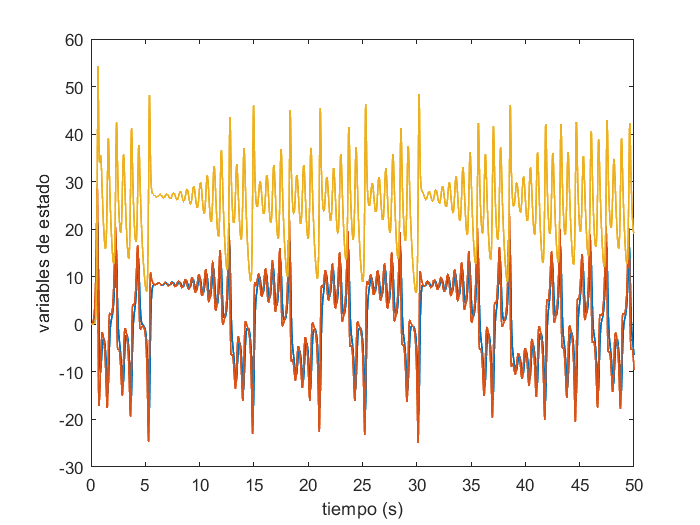

t = t0:dt:tf;
figure;
plot(t, X', 'LineWidth', 1);
xlabel('tiempo (s)');
ylabel('variables de estado');

O bien la trayectoria del sistema en el espacio de estados:

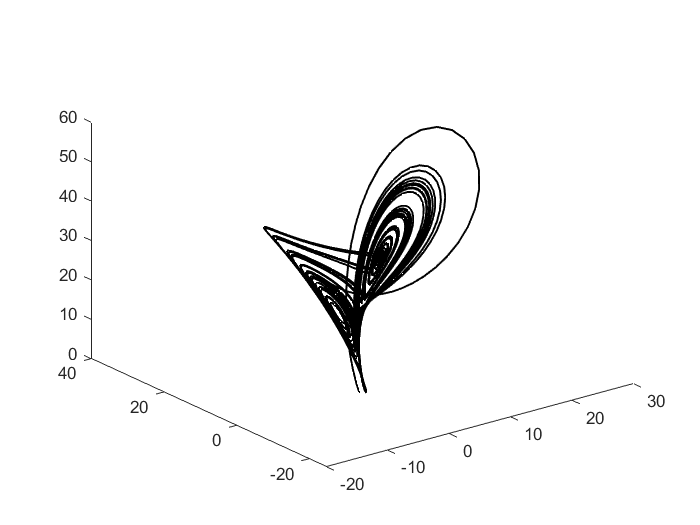

figure;
plot3(X(1,:)', X(2,:)', X(3,:)', 'k', 'LineWidth', 1);